## BIV-Übung 5

Hadi Saleh 1822230

a)

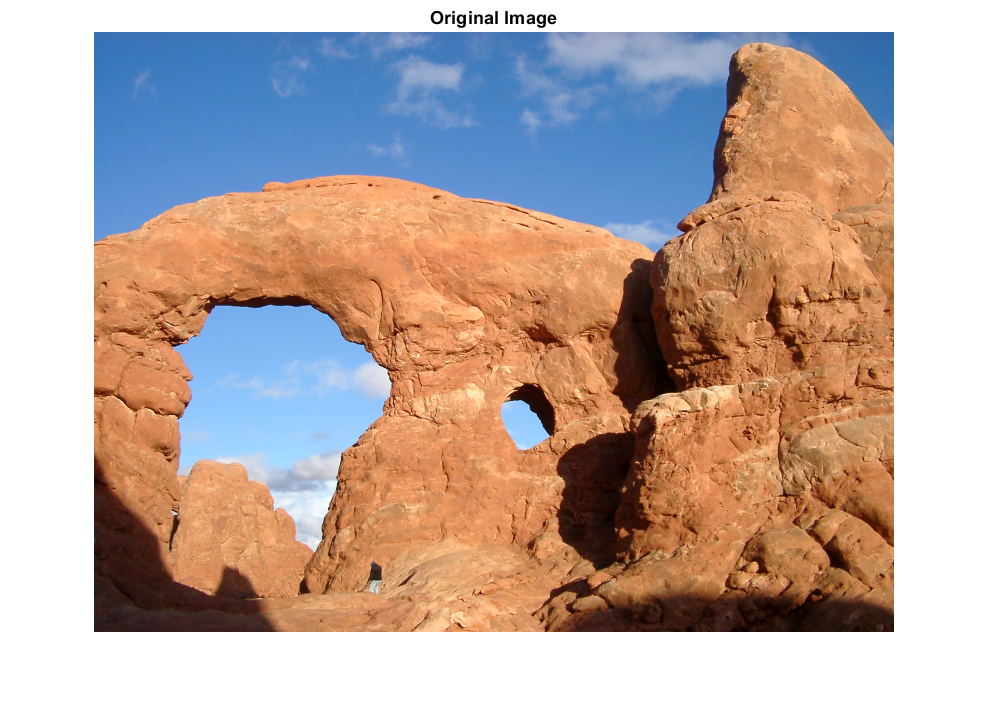

image = imread("archesrgbklein.png");
figure;
imshow(image);
title("Original Image");

b)

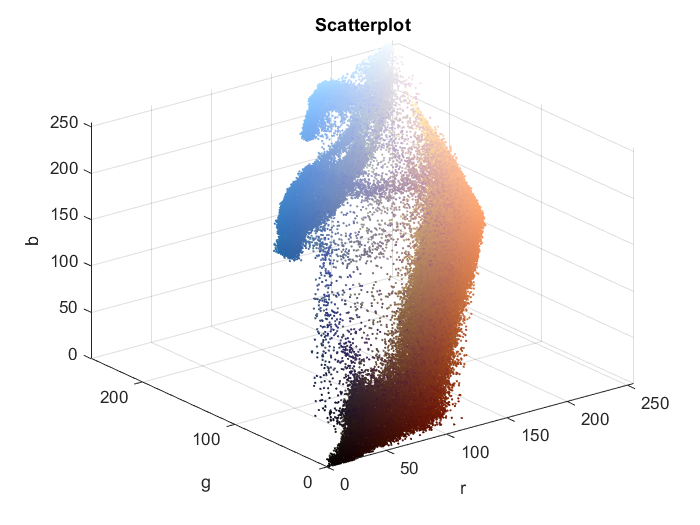

list_rgb = reshape(image, [], 3);
figure;
scatter3(list_rgb(:, 1), list_rgb(:, 2), list_rgb(:, 3), 1, double(list_rgb) / 255)
xlabel('r')
ylabel('g');
zlabel('b');
title('Scatterplot');
xlim([0 255])
ylim([0 255])
zlim([0 255])

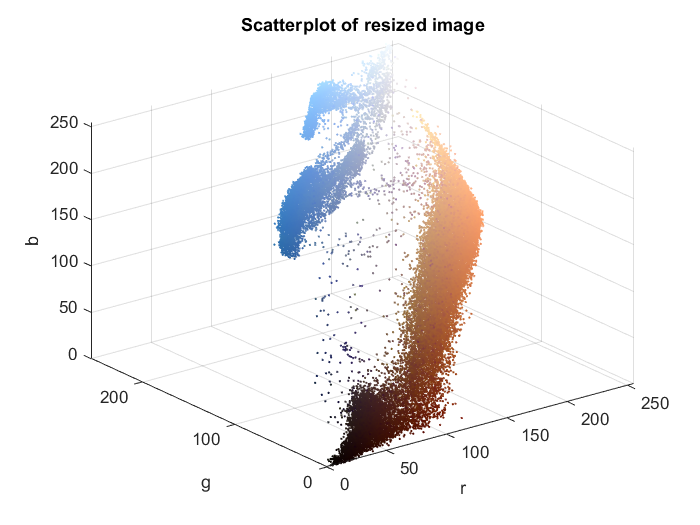


imageResized = imresize(image, 0.4, 'nearest');
list_rgb_resized = reshape(imageResized, [], 3);
figure;
scatter3(list_rgb_resized(:, 1), list_rgb_resized(:, 2), list_rgb_resized(:, 3), 1, double(list_rgb_resized) / 255);
hold on;
xlabel('r');
ylabel('g');
zlabel('b');
title('Scatterplot of resized image');
xlim([0 255])
ylim([0 255])
zlim([0 255])

c)

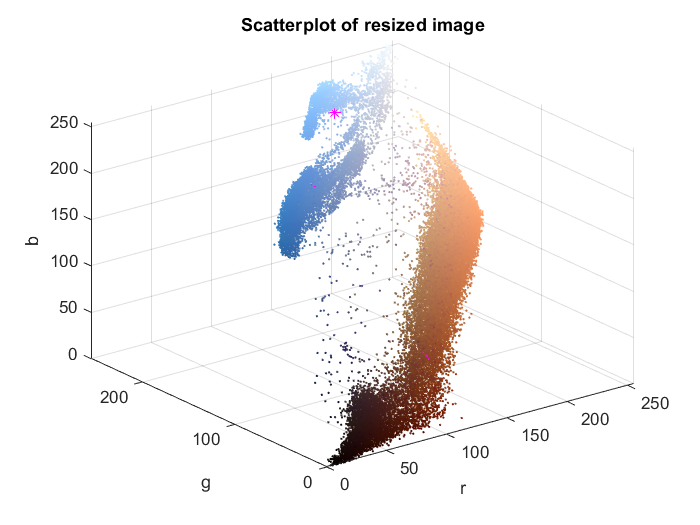


[idx, center] = kmeans(double(list_rgb_resized), 8, 'distance', 'sqeuclidean', 'Replicates', 3);
scatter3(center(:, 1), center(:, 2), center(:, 3), 50, 'magenta', '*');
hold off;

d)

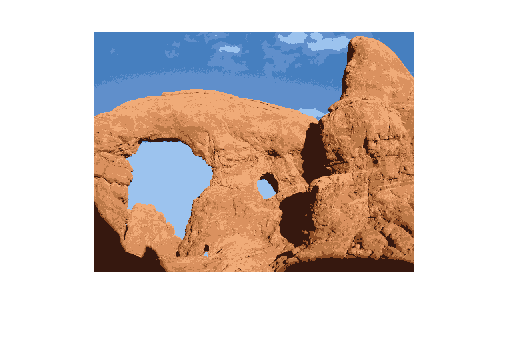

figure;
kmeans_image = uint8(reshape(center(idx, :), size(imageResized)));
imshow(kmeans_image);

e)

[idx_original, center_original] = kmeans(double(reshape(image,[],3)), 8, 'MaxIter', 1, 'Start', center);

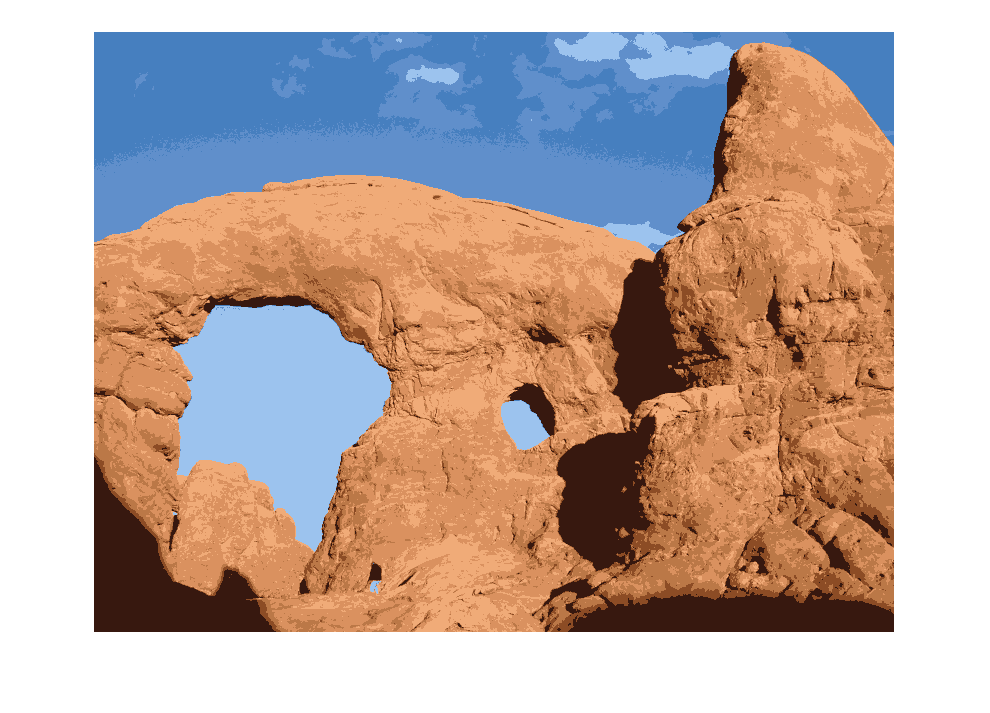

kmeans_image_original = uint8(reshape(center_original(idx_original, :), size(image)));
imshow(kmeans_image_original);

Mit nur einer Iteration kann der Algorithmus nicht wirklich herausfinden ob das Clustering konvergiert oder nicht weil es nur 2 Werte gibt zu vergleichen, aber die Start-werte kommen aus einem pass mit 3 Iterationen und die hat bestimmt schon konvergiert, da wir vorhin keine Fehlermeldung bekommen haben, deshalb können wir hier sicher sein dass die Start-werte gut genug sind und die Warnung ignorieren.

f)

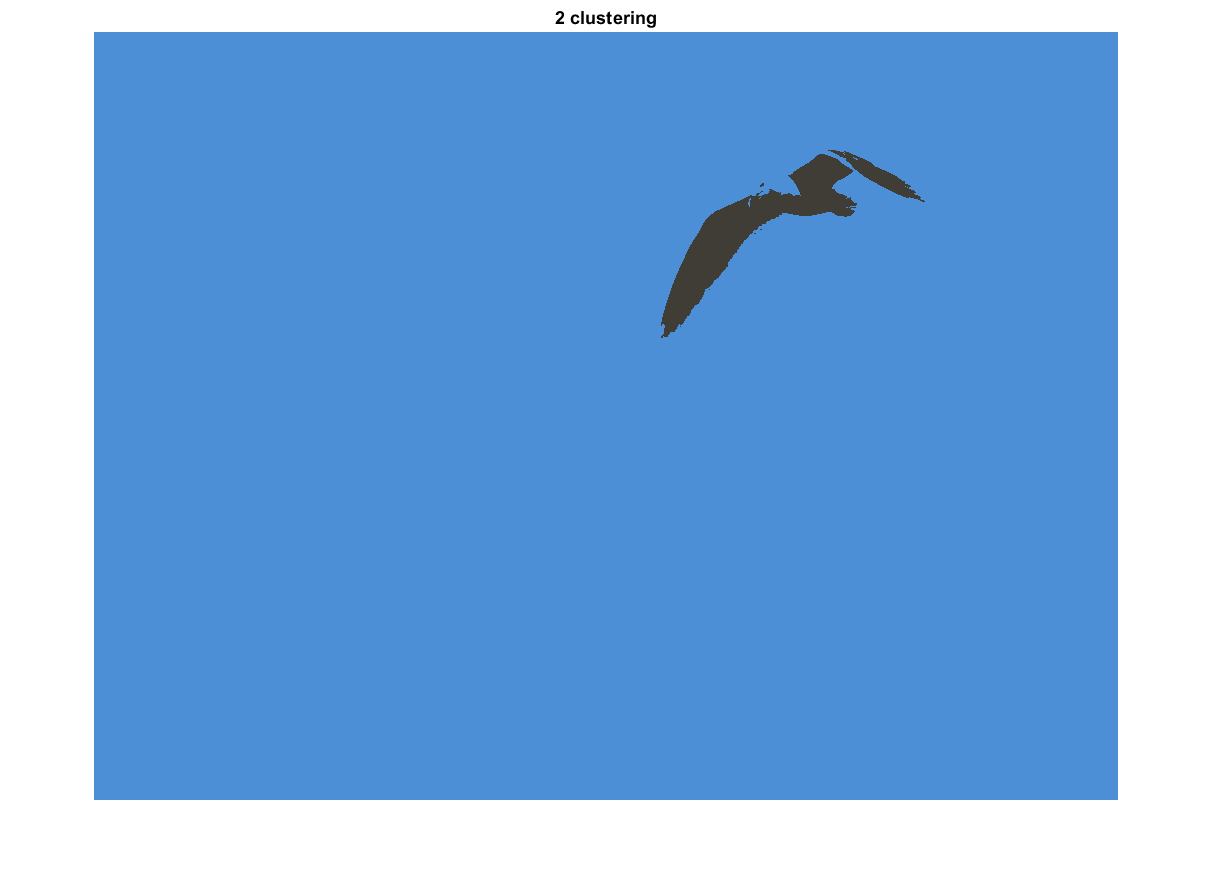

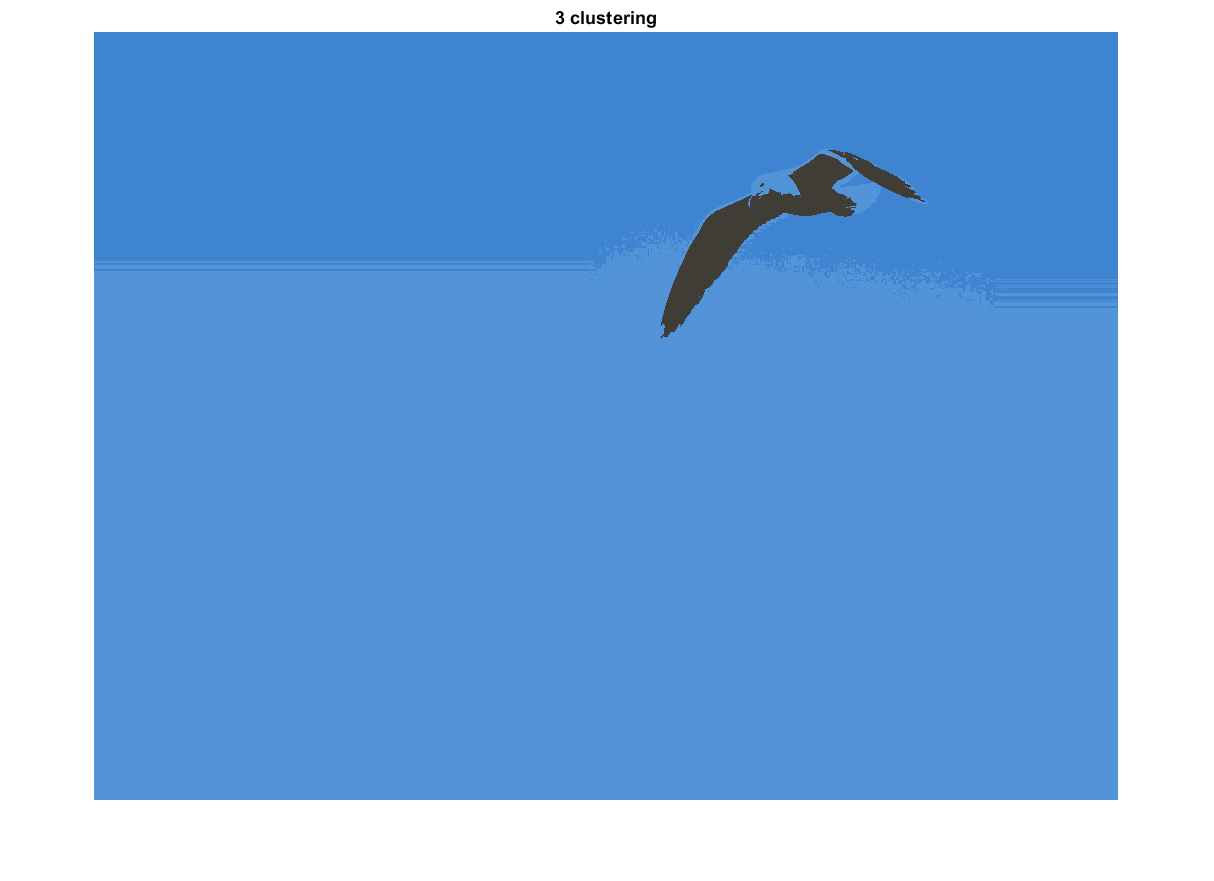

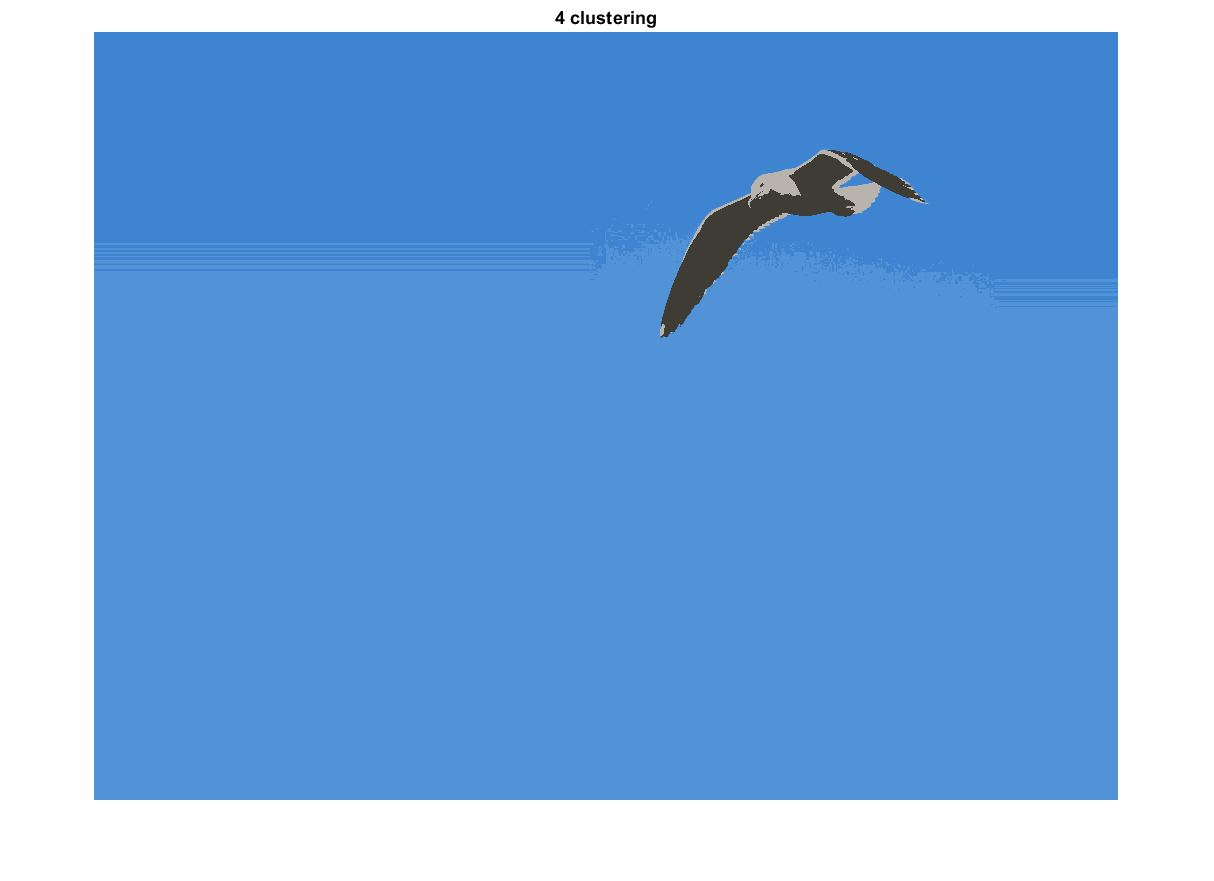

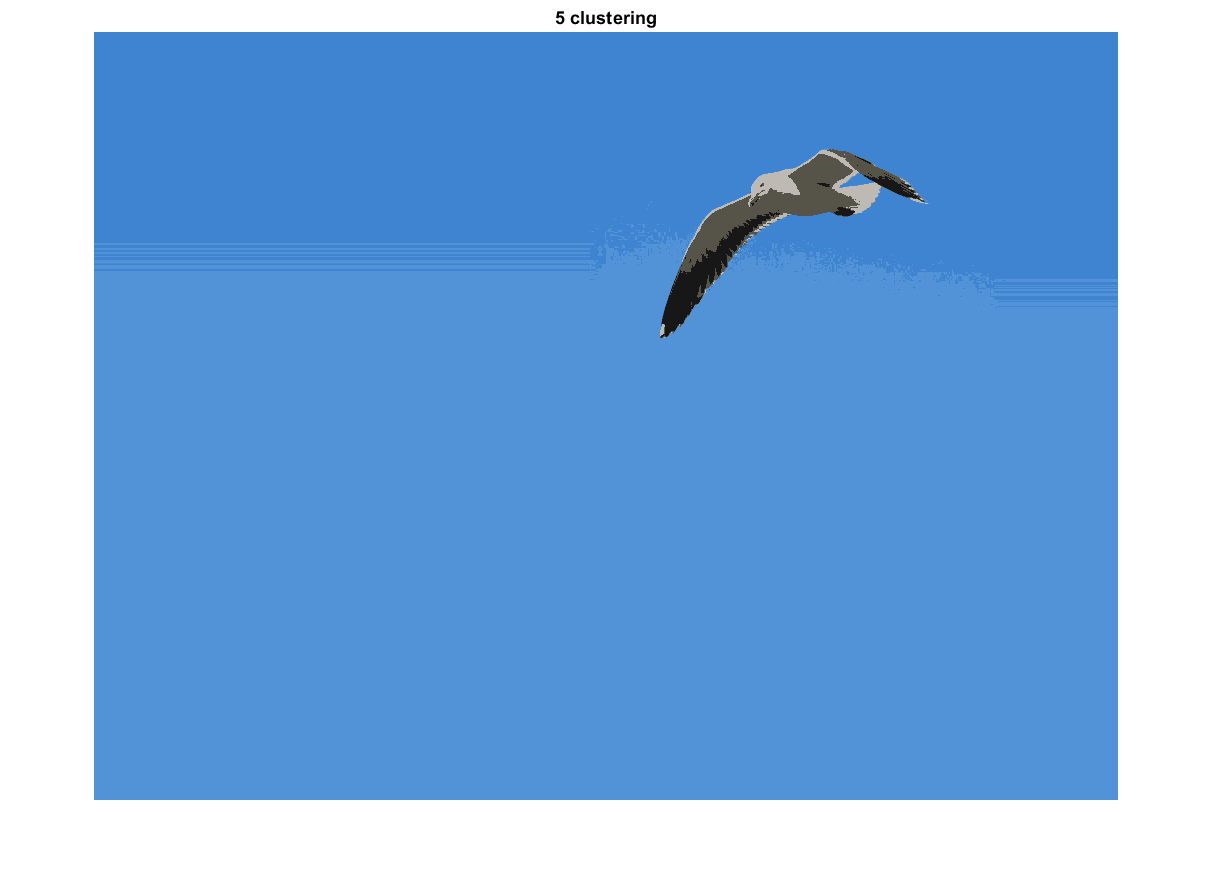

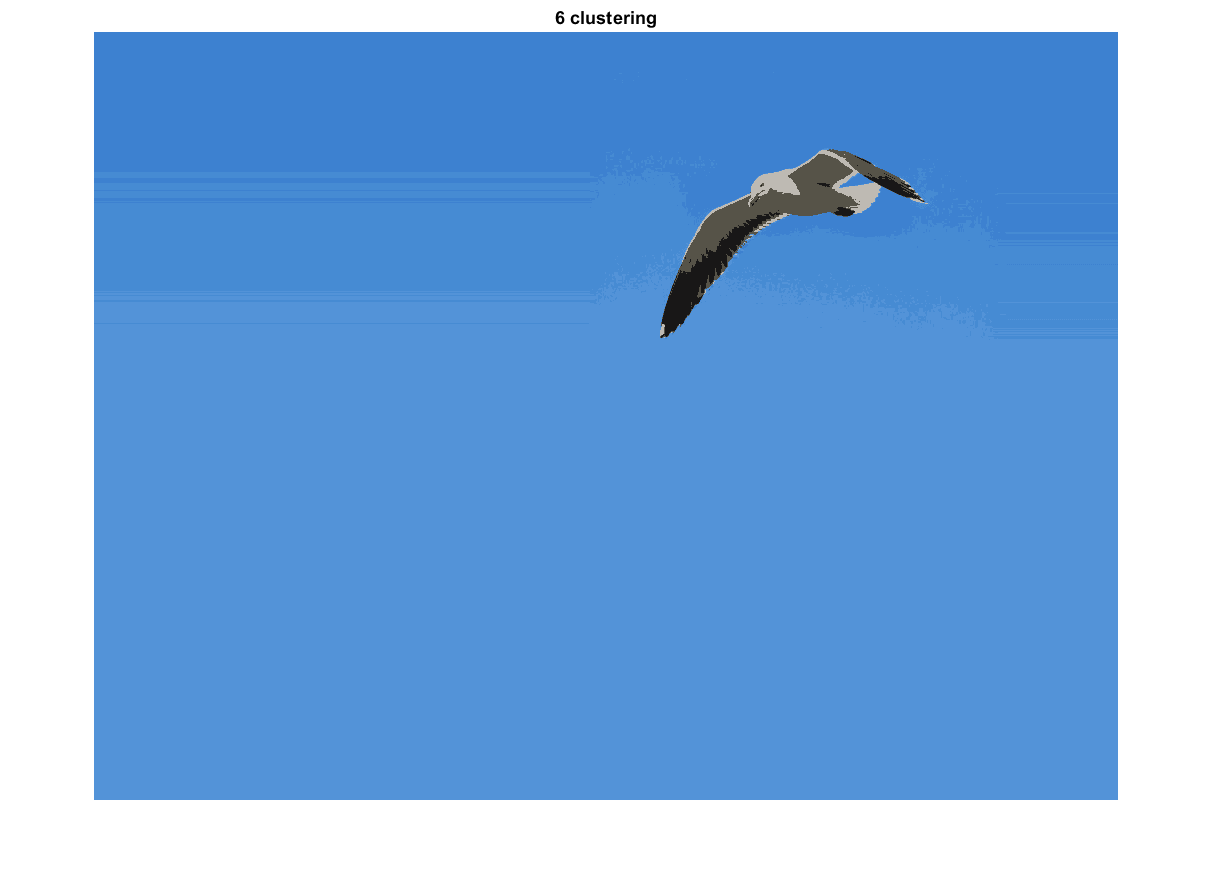

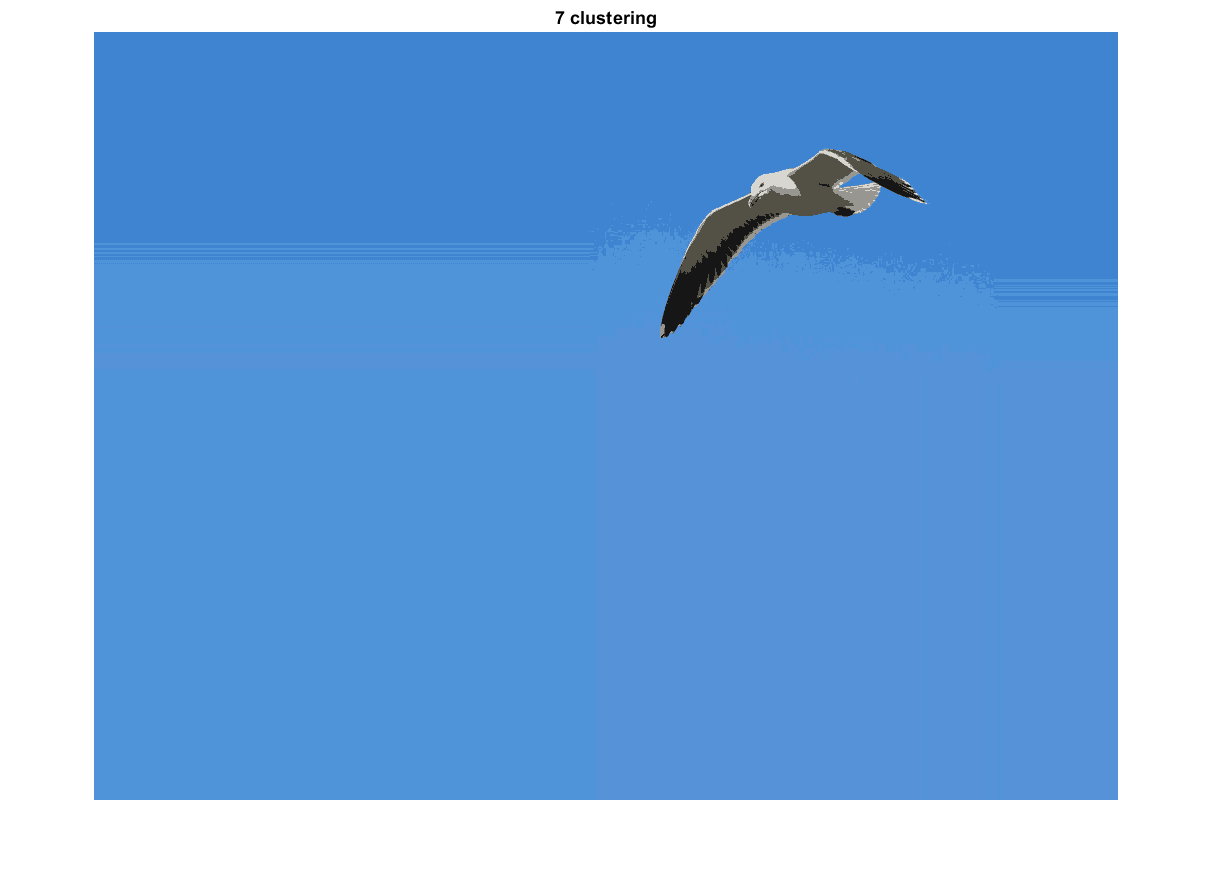

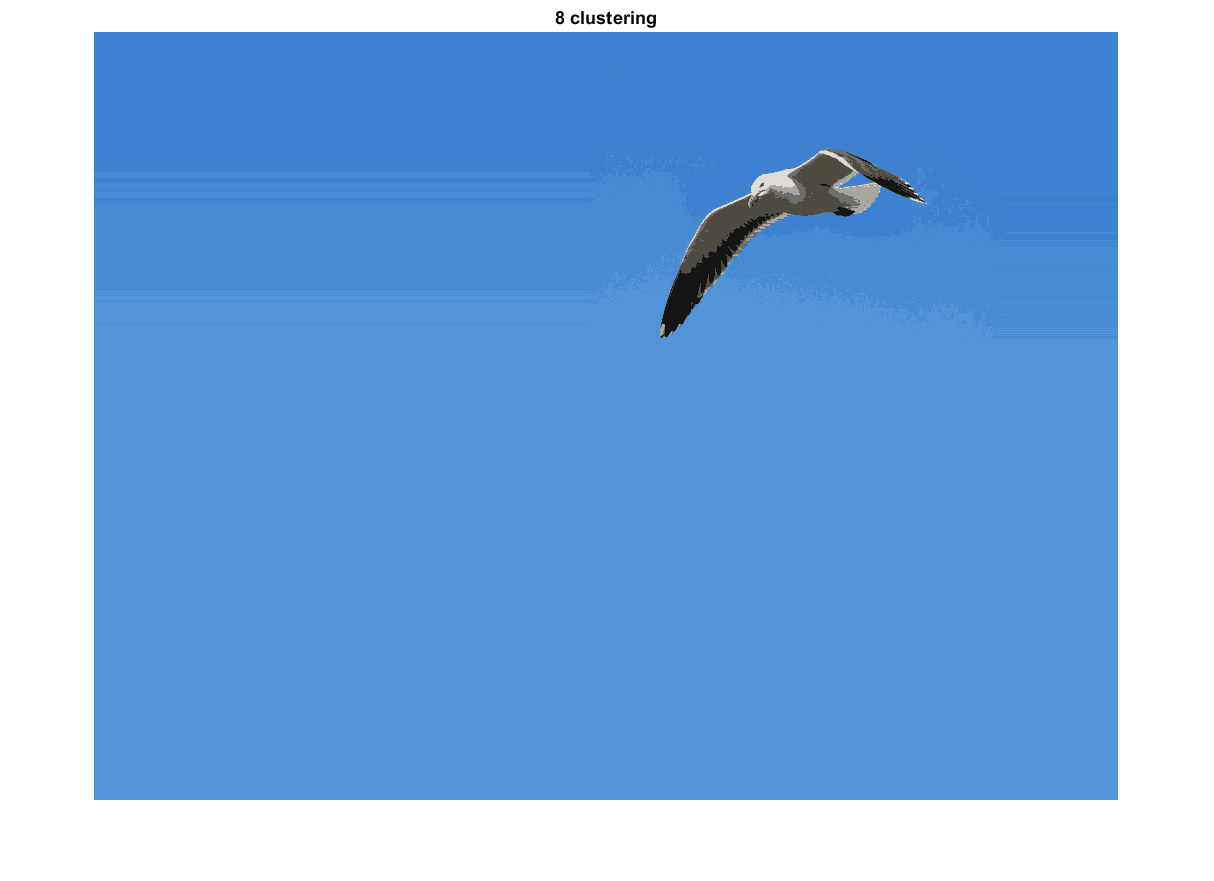

image2 = imread("moewex.jpg");
for i = 2:8
    [idx2, center2] = kmeans(double(reshape(image2, [], 3)), i, 'distance', 'sqeuclidean', 'Replicates', 3);
    kmeans_image2 = uint8(reshape(center2(idx2, :), size(image2)));
    figure;
    imshow(kmeans_image2);
    title(i + " clustering");
    drawnow;
end

g)

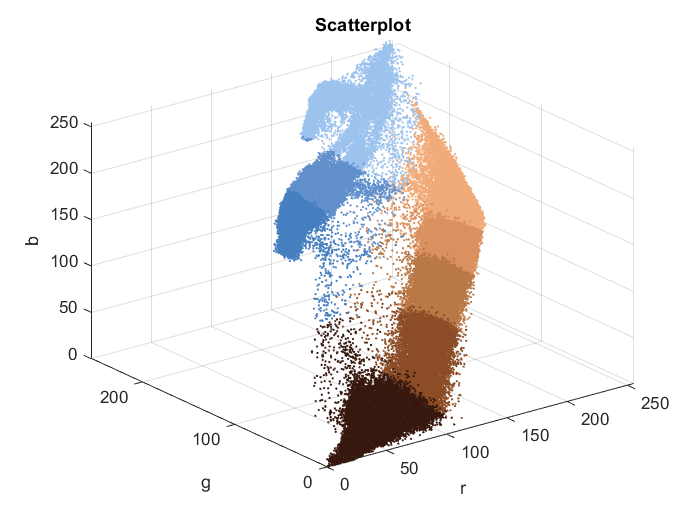

list_rgb1 = reshape(image, [], 3);
list_rgb2 = reshape(kmeans_image_original, [], 3);
figure;
scatter3(list_rgb1(:, 1), list_rgb1(:, 2), list_rgb1(:, 3), 1, double(list_rgb2) / 255)
xlabel('r')
ylabel('g');
zlabel('b');
title('Scatterplot');
xlim([0 255])
ylim([0 255])
zlim([0 255])